# **Numerical Solutions to ODEs **

## **1. Basic Idea**

Consider the initial value problem for first order ordinary differential equations of the form


$$u^\prime=f(t,u), 
\quad
u(0)=u_0,$$


where $u(t)$ is an unknown function of $t$, $f(t,u)$ is a given smooth function, and $u_0$ is a given initial data. This initial value problem is equivalent to the integral equation 


$$u(t)
=
u_0
+
\int_0^t
f\bigl(s,u(s)\bigr)
ds.$$


Let $u(t)$ be a solution to $u^\prime=f(t,u)$. Fix arbitrary $t\in\mathbb{R}$. We denote by $h>0$ the small step size of the approximation methed in $t$. Then we have 


$$u(t+h)
=
u(t)
+
\int_0^h
f\bigl(t+s,u(t+s)\bigr)
ds$$



$$\qquad
=
u(t)+hf\bigl(t,u(t)\bigr)
+
\int_0^h
\bigl\{
f\bigl(t+s,u(t+s)\bigr)
-
f\bigl(t,u(t)\bigr)
\bigr\}
ds$$



$$\qquad
=
u(t)+hf\bigl(t,u(t)\bigr)
+
\text{I}+\text{II},$$



$$\text{I}
=
\int_0^h
\Bigl\{
f\Bigl(t+s,u(t)+sf\bigl(t,u(t)\bigr)\Bigr)
-
f\bigl(t,u(t)\bigr)
\Bigr\}
ds,$$



$$\text{II}
=
\int_0^h
\Bigl\{
f\bigl(t+s,u(t+s)\bigr)
-
f\Bigl(t+s,u(t)+sf\bigl(t,u(t)\bigr)\Bigr)
\Bigr\}
ds.$$


Taylor's theorem implies that 


$$\text{I}
=
\int_0^h
\Bigl\{
sf_t\bigl(t,u(t)\bigr)
+
sf\bigl(t,u(t)\bigr) f_u\bigl(t,u(t)\bigr)
+
\mathcal{O}(s^2)
\Bigr\}
ds$$



$$\quad
=
\frac{h^2}{2}
\Bigl\{
f_t\bigl(t,u(t)\bigr)
+
f\bigl(t,u(t)\bigr) f_u\bigl(t,u(t)\bigr)
\Bigr\}
+
\mathcal{O}(h^3).$$


Since $u(t)$ is a solution to $u^\prime=f(t,u)$, we deduce by Taylor's formula that 


$$u(t+s)-u(t)-sf\bigl(t,u(t)\bigr)
=
u(t+s)-u(t)-su^\prime(t)
=
\mathcal{O}(s^2).$$


Hence, by using the mean value theorem, we deduce that 


$$\text{II}
=
\int_0^h
f_u(t+s,\cdots)
\bigl\{
u(t+s)
-
u(t)sf\bigl(t,u(t)
\Bigr\}
ds$$



$$\quad
=
\int_0^h
\mathcal{O}(s^2)
ds
=
\mathcal{O}(h^3).$$


Combining the above results, we obtain 


$$u(t+h)
=
u(t)
+
hf\bigl(y,u(t)\bigr)
+
\frac{h^2}{2}
\Bigl\{
f_t\bigl(t,u(t)\bigr)
+
f\bigl(t,u(t)\bigr) f_u\bigl(t,u(t)\bigr)
\Bigr\}
+
\mathcal{O}(h^3)$$



$$\qquad\quad
=
u(t)
+
hf\bigl(y,u(t)\bigr)
+
\mathcal{O}(h^2).$$


## 2. The Euler Method

Let $h>0$ be a step size in $t$. The approximate solution is denoted by 


$$U_0:=u_0,
\quad
U_j
\simeq
u(jh),
\quad
j=1,2,3,\ldots.$$


We set 


$$F_j:=f(jh,U_j),
\quad
F_{t,j}:=f_t(jh,U_j),
\quad
F_{u,j}:=f_u(jh,U_j),
\quad
j=0,1,2,\ldots.$$


### The Euler Method

If we neglect $\mathcal{O}(h^2)$ and employ 


$$u(t+h)
\simeq
u(t)
+
hf\bigl(y,u(t)\bigr),$$


then the approximation scheme is 


$$U_{j+1}:=U_j+hF_j.$$


### Second Order Version

If we neglect $\mathcal{O}(h^3)$ and employ 


$$u(t+h)
\simeq
u(t)
+
hf\bigl(y,u(t)\bigr)
+
\frac{h^2}{2}
\Bigl\{
f_t\bigl(t,u(t)\bigr)
+
f\bigl(t,u(t)\bigr) f_u\bigl(t,u(t)\bigr)
\Bigr\},$$


then the approximation scheme is 


$$U_{j+1}:=U_j+hF_j
+
\frac{h^2}{2}
\bigl(F_{t,j}+F_jF_{u,j}\bigr).$$


## 3. $u^\prime=u, u(0)=1$

The approximation schemes are the following:

The Euler Method


$$U_{j+1}
=
U_j+hU_j,$$


Second Order Version


$$U_{j+1}=U_j+hU_j+\frac{h^2}{2}U_j.$$


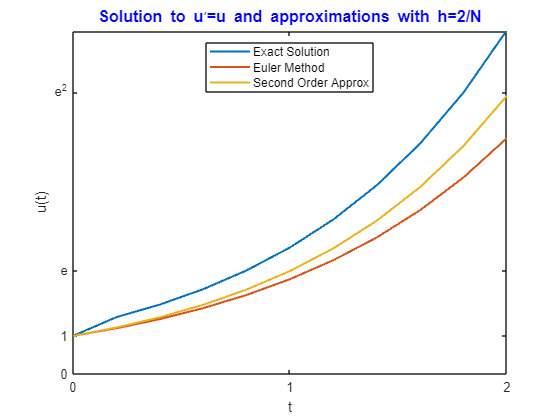

syms u(t)
ode1=diff(u,t,1)-u;
data1=u(0)==1;
U0(t)=dsolve(ode1,data1);
N =10;
h=2/N;
t=0:h:2;
strd1=string(h);
U1=zeros(1,N+1);
U2=zeros(1,N+1);
U3=zeros(1,N+1);
U1(1,1)=1;
U2(1,1)=1;
U3(1,1)=1;
for j=2:N+1
    U1(1,j)=U0(j*h);
    U2(1,j)=U2(1,j-1)+h*U2(1,j-1);
    U3(1,j)=U3(1,j-1)+h*U3(1,j-1)+h^2*U3(1,j-1)/2;
end

plot(t,U1,t,U2,t,U3,'LineWidth',1.5)
xlim([0,2])
ylim([0,9])
xlabel('t')
xticks([0 1 2])
%xticklabels({'0','1','2'})
ylabel('u(t)')
yticks([0 1 exp(1) exp(2)])
yticklabels({'0','1','e','e^2'})
title('Solution to u^\prime=u and approximations with h=2/N','Color','blue','FontSize',12)
legend('Exact Solution','Euler Method','Second Order Approx','Location','north')

## 4. $u^\prime=u^2, u(0)=1$

The approximation schemes are the following:

The Euler Method


$$U_{j+1}
=
U_j+hU_j^2,$$


Second Order Version


$$U_{j+1}=U_j+hU_j^2+h^2U_j^3.$$


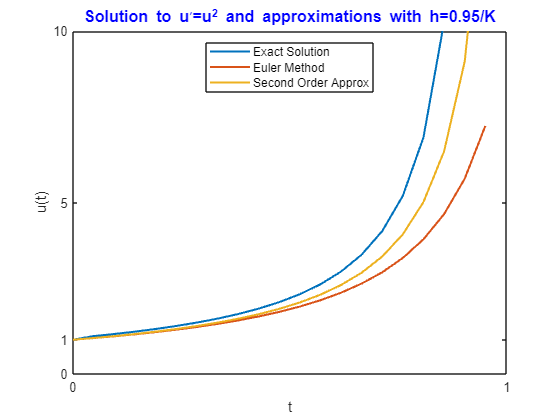

syms v(s)
ode2=diff(v,s,1)-v^2;
data2=v(0)==1;
V0(s)=dsolve(ode2,data2);
K =20;
k=0.95/K;
s=0:k:0.95;
V1=zeros(1,K+1);
V2=zeros(1,K+1);
V3=zeros(1,K+1);
V1(1,1)=1;
V2(1,1)=1;
V3(1,1)=1;
for j=2:K+1
    V1(1,j)=V0(j*k);
    V2(1,j)=V2(1,j-1)+k*V2(1,j-1)^2;
    V3(1,j)=V3(1,j-1)+k*V3(1,j-1)^2+k^2*V3(1,j-1)^3;
end

plot(s,V1,s,V2,s,V3,'LineWidth',1.5)
xlim([0,1])
ylim([0,10])
xlabel('t')
xticks([0 1])
%xticklabels({'0','1'})
ylabel('u(t)')
yticks([0 1 5 10])
yticklabels({'0','1','5','10'})
title('Solution to u^\prime=u^2 and approximations with h=0.95/K','Color','blue','FontSize',12)
legend('Exact Solution','Euler Method','Second Order Approx','Location','north')

## 5. MATLAB ODE Solvers

MATLAB has some ODE solvers: ode45, ode23, ode113, ode78, ode89, ode15s,ode23s,ode23t, ode23tb, ode15i. They solve the initial value problem, and integrate the equation or the system step by step. MathWorks recommends the use of **ode45**. See the link below for the detail. 

[Choose an ODE Solver](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

We use ode45 to solve the initial value problem for the SIR model for infection disease of the form 


$$S^\prime=-\beta IS, 
\quad
I^\prime=\beta IS-\gamma I, 
\quad
R^\prime=\gamma I, $$


where $S(t)$, $I(t)$ and $R(t)$ are real-value unknown functions of $t$,  and $\beta$ and $\gamma$ are positive constants.  In mathematical epidemiology, $t$ is time, $S(t)$ is the number of susceptible people, $I(t)$ is the number of people infected, $R(t)$ is the number of people who have recovered and developed immunity to the infection, $\beta$ is the infection rate, and $\gamma$ is the recovery rate. 

Since $(S+I+R)^\prime=0$, the total poputation $N$ is preserved in this model. So we rewrite as 


$$S:=S/N, 
\quad
I:=I/N, 
\quad
R:=R/N,
\quad
\beta:=\beta{N}, 
\quad
\gamma:=\gamma.$$


Then we have apparently the same system 


$$S^\prime=-\beta IS, 
\quad
I^\prime=\beta IS-\gamma I, 
\quad
R^\prime=\gamma I, $$


In this setting 


$$\rho_\text{e}(t):=\frac{\gamma S(t)}{\gamma}, 
\quad
\rho_0:=\frac{\beta}{\gamma}$$


are said to be the effective reproduction number  and the basic reproduction number respectively.  Note that ,  and that the signature of  shows the   increase/decrease of the number of active cases .   For this reason    is the most important function in mathematical epidemiology.  

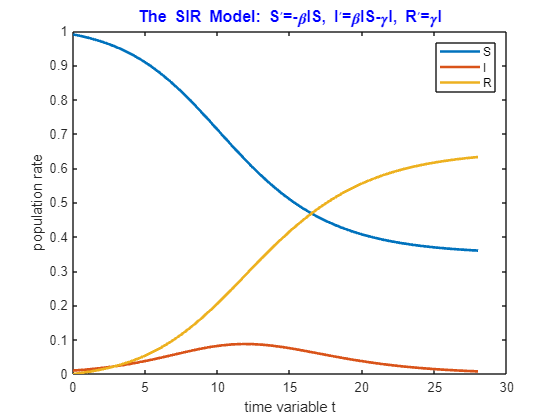

 beta =0.8 ; 
gamma =0.5;
[t1,u1]=ode45(@(t,u) [-beta*u(1)*u(2); beta*u(1)*u(2)-gamma*u(2); gamma*u(2)], [0,28], [0.99;0.01;0]);

plot(t1,u1(:,1),t1,u1(:,2),t1,u1(:,3),'LineWidth',2); title('The SIR Model: S^\prime=-\beta{IS}, I^\prime=\beta{IS}-\gamma{I}, R^\prime=\gamma{I}','Color','blue','FontSize',12); xlabel('time variable t'); 
ylabel('population rate');
legend('S','I','R');